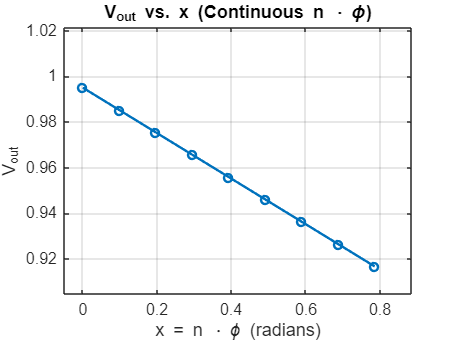

clear; clc;

phi = pi / 32; 


V_neg1 = cos(0.1 - phi);
V_0 = cos(0.1);
V_1 = cos(0.1 + phi);


ABk = - (V_1 - V_neg1) / phi;


delta_theta = 1 - (2 * V_0 / ABk);

x_values = (0:8) * phi; 
Vout_values = zeros(size(x_values)); 


for i = 1:length(x_values)
    x = x_values(i);
    Vout_values(i) = (ABk / 2) * (1-delta_theta-x);
end


figure;
plot(x_values, Vout_values, '-o', 'LineWidth', 1.5, 'MarkerSize', 5);


xlabel('x = n \cdot \phi (radians)');
ylabel('V_{out}');
title('V_{out} vs. x (Continuous n \cdot \phi)');
grid on;